## Experiment Name and Patient specification

ExperimentName = "Exp2_SVM_ANOVA_BayesianOptimization";

%Variables that vary per patient allowing quick interchanging
PatientID = "P10";
ChosenTableString = "IPDTable"; 

%Feature selection
startingNumberofFeatures = 1; 
stepsize = 1; 
totalNumberofFeatures = 1; 

numFeaturesToKeep = 10; %Features that will determine cross-validation results

 

%Makes the file for storing all the required information for the specific
%experiemnt.
if ispc
        % For Windows
        folderPath = fullfile(sprintf('..\\OwnResults\\%sRH\\%s',PatientID,ExperimentName));
        
        % Check if the folder exists; if not, create it
        if ~exist(folderPath, 'dir')
            mkdir(folderPath);
        end
    

    elseif ismac
        folderPath = fullfile(sprintf('../OwnResults/%sRH/%s',PatientID,ExperimentName));
        
        % Check if the folder exists; if not, create it
        if ~exist(folderPath, 'dir')
            mkdir(folderPath);
        end
    
end

## Generate all the IDP and PLV value if required

% PatientIDs = {'P10'}; 
% 
% GenerateIPD_PLVTables(PatientIDs); 

## Load a specific patients data to allow Classification learn to Use specific data 

if ispc
        % For Windows
        % Construct the file path using sprintf
        IPDTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\IPDTable.mat', PatientID)).IPDTable;
        PLVTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\PLVTable.mat', PatientID)).PLVTable;
        IPD_PLVTable = load(sprintf('..\\OwnResults\\%sRH\\MatlabGeneratedData\\IPD_PLVTable.mat', PatientID)).IPD_PLVTable;
    elseif ismac
        IPDTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/IPDTable.mat', PatientID)).IPDTable;
        PLVTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/PLVTable.mat', PatientID)).PLVTable;
        IPD_PLVTable = load(sprintf('../OwnResults/%sRH/MatlabGeneratedData/IPD_PLVTable.mat', PatientID)).IPD_PLVTable;
end

% Use a switch statement to match the table name and assign the correct table
switch ChosenTableString
    case 'IPDTable'
        ChosenTable = IPDTable; 
    case 'PLVTable'
        ChosenTable = PLVTable; 
    case 'IPD_PLVTable'
        ChosenTable = IPD_PLVTable; 
    otherwise
        error('Table name not recognized.');
end


## ANOVA one way but determining the best number of features for highest accuracy

   200     1



|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |        0.55 |    0.056947 |        0.55 |        0.55 |      0.29686 |      0.11528 |
|    2 | Best   |        0.44 |    0.044774 |        0.44 |     0.44726 |      0.20185 |       772.15 |
|    3 | Accept |        0.44 |    0.071517 |        0.44 |      0.4436 |       308.27 |       6.1534 |
|    4 | Accept |       0.475 |    0.061517 |        0.44 |     0.44299 |       369.75 |     0.017995 |
|    5 | Accept |       0.445 |    0.047648 |        0.44 |        0.44 |      0.36224 |       717.98 |
|    6 | Accept |        0.44 |     0.05255 |        0.44 |     

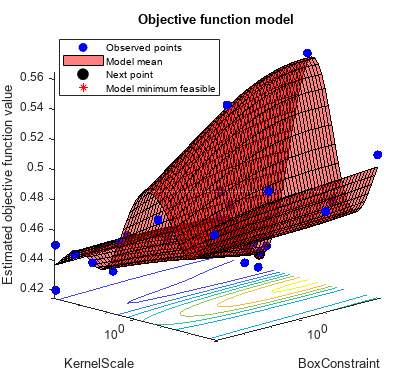

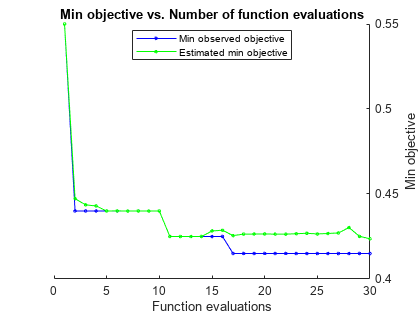


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 12.8152 seconds
Total objective function evaluation time: 1.6534

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       996.52          85.406   

Observed objective function value = 0.415
Estimated objective function value = 0.43086
Function evaluation time = 0.043951

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       968.83          23.391   

Estimated objective function value = 0.42366
Estimated function evaluation time = 0.046407




columnNames = ChosenTable.Properties.VariableNames;
predictorNames = columnNames(1,1:end-1);
isCategoricalPredictor = [false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false, false];


predictors = ChosenTable(:, predictorNames);
response = ChosenTable.Class;

predictors = standardizeMissing(predictors, {Inf, -Inf});
predictorMatrix = normalize(predictors);
newPredictorMatrix = zeros(size(predictorMatrix));

for i = 1:size(predictorMatrix, 2)
    if isCategoricalPredictor(i)
        newPredictorMatrix(:,i) = grp2idx(predictorMatrix{:,i});
    else
        newPredictorMatrix(:,i) = predictorMatrix{:,i};
    end
end
predictorMatrix = newPredictorMatrix;
responseVector = grp2idx(response);

% Rank features using ANOVA algorithm
for i = 1:size(predictorMatrix, 2)
    pValues(i) = anova1(...
        predictorMatrix(:,i), ...
        responseVector, ...
        'off');
end
[~,featureIndex] = sort(-log(pValues), 'descend');


%Generating the plot to determine the best number of features
accuracies = [];
numberofFeatures = []; 


for i = startingNumberofFeatures:stepsize:totalNumberofFeatures
    includedPredictorNames = predictors.Properties.VariableNames(featureIndex(1:i));
    iterationspredictors = predictors(:,includedPredictorNames);
    numberofFeatures = [numberofFeatures, i]; 

    disp(size(iterationspredictors))

    % Define the SVM model function for Bayesian Optimization
    svmModel = @(params)fitcsvm(iterationspredictors, response, ...
        'KernelFunction', 'rbf', ...
        'BoxConstraint', params.BoxConstraint, ...
        'KernelScale', params.KernelScale, ...
        'Standardize', true, ...
        'CrossVal', 'on', ...
        'KFold', 10);
    
    % Define the optimization variables
    optimVars = [
        optimizableVariable('BoxConstraint', [1e-3, 1e3], 'Transform', 'log');
        optimizableVariable('KernelScale', [1e-3, 1e3], 'Transform', 'log')
        ];
    
    % Define the objective function for Bayesian optimization
    minfn = @(params)kfoldLoss(svmModel(params));
    
    % Run Bayesian Optimization
    results = bayesopt(minfn, optimVars, ...
        'MaxObjectiveEvaluations', 30, ...
        'Verbose', 1, ...
        'IsObjectiveDeterministic', false, ...
        'AcquisitionFunctionName', 'expected-improvement-plus');
    
    % Extract the best hyperparameters
    bestParams = bestPoint(results);

    numFolds = 10; % Number of folds for cross-validation
    rng(1); % Fixed seed for consistent results
    
    % Use the full combined table for cross-validation
    xtrain = iterationspredictors;
    ytrain = response;
    cvPartition = cvpartition(ytrain, 'KFold', numFolds, 'Stratify', true);
    
    
    foldAccuracy = zeros(numFolds, 1);
    
    for fold = 1:numFolds
        trainIndices = cvPartition.training(fold);
        testIndices = cvPartition.test(fold);
    
        XtrainFold = xtrain(trainIndices, :);
        YtrainFold = ytrain(trainIndices);
        XtestFold = xtrain(testIndices, :);
        YtestFold = ytrain(testIndices);
    
        SVMModel = fitcsvm(XtrainFold, YtrainFold, ...
            'KernelFunction', 'rbf', ...
            'BoxConstraint', bestParams.BoxConstraint, ...
            'KernelScale', bestParams.KernelScale, ...
            'Standardize', true);
    
        YtestPred = predict(SVMModel, XtestFold);
    
        foldAccuracy(fold) = sum(YtestPred == YtestFold) / length(YtestFold);
    end

        accuracies = [accuracies, mean(foldAccuracy)];
end 

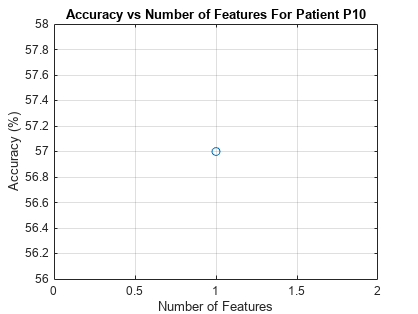


% Create the plot
figure; % Open a new figure window
plot(numberofFeatures, 100.*accuracies, '-o');
xlabel('Number of Features');
ylabel('Accuracy (%)');
title(sprintf('Accuracy vs Number of Features For Patient %s',PatientID));
grid on;

## Store the plot and its corresponding data 

%Required to store the accuracies and the number of features for the
%feature selection stage. 

% Define the path for Anova Feature Selection folder
anovaFolderPath = fullfile(folderPath, 'AnovaFeatureSelection');

anovaFolderPath = fullfile(anovaFolderPath,ChosenTableString);

% Check if the folder exists, if not, create it
if ~exist(anovaFolderPath, 'dir')
    mkdir(anovaFolderPath);
end

% Construct the filename using the specified format
fileName = sprintf('%s_%d_%d_%d.mat', ...
                   ChosenTableString,startingNumberofFeatures, stepsize, totalNumberofFeatures);

% Full path to save the .mat file in the AnovaFeatureSelection folder
fullFilePath = fullfile(anovaFolderPath, fileName);

% Construct the filename using the specified format
plotFileName = sprintf('%s_%d_%d_%d.fig', ...
                       ChosenTableString,startingNumberofFeatures, stepsize, totalNumberofFeatures);
plotFileNamePNG = sprintf('%s_%d_%d_%d.png', ...
                       ChosenTableString,startingNumberofFeatures, stepsize, totalNumberofFeatures);

% Full path to save the plot in the AnovaFeatureSelection folder
fullPlotPath = fullfile(anovaFolderPath, plotFileName);
fullPlotPathPNG = fullfile(anovaFolderPath, plotFileNamePNG);
% Save the accuracies and number of features to the .mat file
save(fullFilePath, 'accuracies', 'numberofFeatures');

% Save the plot with the constructed filename
saveas(gcf, fullPlotPath);
saveas(gcf, fullPlotPathPNG);

## Select ideal number of features

includedPredictorNames = predictors.Properties.VariableNames(featureIndex(1:numFeaturesToKeep));
predictors = predictors(:,includedPredictorNames);

## Hyperparameter tuning

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |         0.5 |    0.057494 |         0.5 |         0.5 |      0.29686 |      0.11528 |
|    2 | Best   |        0.46 |     0.04731 |        0.46 |     0.46264 |      0.20185 |       772.15 |
|    3 | Best   |        0.45 |     0.14028 |        0.45 |     0.45236 |       308.27 |       6.1534 |
|    4 | Accept |         0.5 |    0.059692 |        0.45 |        0.45 |       369.75 |     0.017995 |
|    5 | Best   |       0.405 |    0.050741 |       0.405 |     0.40503 |       1.3729 |       33.605 |
|    6 | Accept |       0.445 |    0.047784 |       0.405 |     

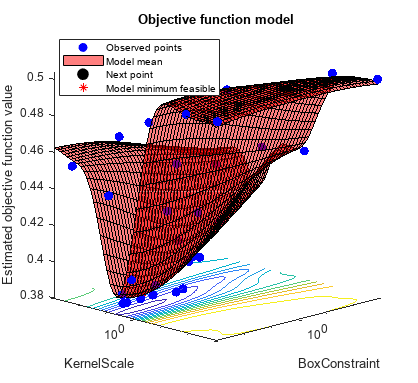

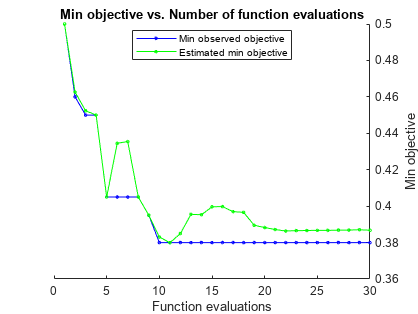


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 12.7137 seconds
Total objective function evaluation time: 1.613

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       1.0959          18.228   

Observed objective function value = 0.38
Estimated objective function value = 0.39965
Function evaluation time = 0.049695

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

      0.0084664        5.1659   

Estimated objective function value = 0.38677
Estimated function evaluation time = 0.049896



% Define the SVM model function for Bayesian Optimization
svmModel = @(params)fitcsvm(predictors, response, ...
    'KernelFunction', 'rbf', ...
    'BoxConstraint', params.BoxConstraint, ...
    'KernelScale', params.KernelScale, ...
    'Standardize', true, ...
    'CrossVal', 'on', ...
    'KFold', 10);

% Define the optimization variables
optimVars = [
    optimizableVariable('BoxConstraint', [1e-3, 1e3], 'Transform', 'log');
    optimizableVariable('KernelScale', [1e-3, 1e3], 'Transform', 'log')
    ];

% Define the objective function for Bayesian optimization
minfn = @(params)kfoldLoss(svmModel(params));

% Run Bayesian Optimization
results = bayesopt(minfn, optimVars, ...
    'MaxObjectiveEvaluations', 30, ...
    'Verbose', 1, ...
    'IsObjectiveDeterministic', false, ...
    'AcquisitionFunctionName', 'expected-improvement-plus');


% Extract the best hyperparameters
bestParams = bestPoint(results);

%box constraint = 991.6607
%kernel scale = 561.2574
%with 50 features for P3


## Store the hyperparameters 

% Define the path for Anova Feature Selection folder
hyperparametertuningFolderPath = fullfile(folderPath, 'HyperParameterTuning');


hyperparametertuningFolderPath = fullfile(hyperparametertuningFolderPath,ChosenTableString);


% Check if the folder exists, if not, create it
if ~exist(hyperparametertuningFolderPath, 'dir')
    mkdir(hyperparametertuningFolderPath);
end

% Construct the filename using the specified format
fileName = sprintf('%s_TunedParameters_%d.mat', ...
                   ChosenTableString,numFeaturesToKeep);

% Full path to save the .mat file in the AnovaFeatureSelection folder
fullFilePath = fullfile(hyperparametertuningFolderPath, fileName);

% Save the arrays to the .mat file
save(fullFilePath, 'bestParams');


## Stratified K-fold cross-validation

numFolds = 10; % Number of folds for cross-validation
rng(1); % Fixed seed for consistent results

% Use the full combined table for cross-validation
xtrain = predictors;
ytrain = response;
cvPartition = cvpartition(ytrain, 'KFold', numFolds, 'Stratify', true);


foldAccuracy = zeros(numFolds, 1);
foldPrecision = zeros(numFolds,1);
foldRecall = zeros(numFolds,1);
foldF1Score = zeros(numFolds,1); 

for fold = 1:numFolds
    trainIndices = cvPartition.training(fold);
    testIndices = cvPartition.test(fold);

    XtrainFold = xtrain(trainIndices, :);
    YtrainFold = ytrain(trainIndices);
    XtestFold = xtrain(testIndices, :);
    YtestFold = ytrain(testIndices);

    SVMModel = fitcsvm(XtrainFold, YtrainFold, ...
    'KernelFunction', 'rbf', ...
    'BoxConstraint', bestParams.BoxConstraint, ...
    'KernelScale', bestParams.KernelScale, ...
    'Standardize', true);

    YtestPred = predict(SVMModel, XtestFold);

    foldAccuracy(fold) = sum(YtestPred == YtestFold) / length(YtestFold);
    [foldPrecision(fold), foldRecall(fold), foldF1Score(fold)] = EvaluateModel(YtestPred,YtestFold);
end

meanAccuracy = mean(foldAccuracy);
disp(['Average Cross-Validation Accuracy: ', num2str(meanAccuracy * 100), '%']);

Average Cross-Validation Accuracy: 61%


disp(['Average Cross-Validation Precision: ', num2str(mean(foldPrecision) * 100), '%']);

Average Cross-Validation Precision: 62.175%


disp(['Average Cross-Validation Recall: ', num2str(mean(foldRecall) * 100), '%']);

Average Cross-Validation Recall: 61%


disp(['Average Cross-Validation F1-Score: ', num2str(mean(foldF1Score) * 100), '%']);

Average Cross-Validation F1-Score: 60.2052%


## Store the results of the stratified cross-validation

%Store the results of the stratified k-fold cross-validation 
stratifiedCrossValidationPath = fullfile(folderPath, 'Stratified_K-Fold_CrossValidation');

stratifiedCrossValidationPath = fullfile(stratifiedCrossValidationPath,ChosenTableString);

% Create a filename based on the feature selection parameters
filename = sprintf('%s_EvaluationMetrics_%d.mat',ChosenTableString,numFeaturesToKeep);

% Specify the path where you want to save the file
savePath = fullfile(stratifiedCrossValidationPath, filename);

% Check if the folder exists, if not, create it
if ~exist(stratifiedCrossValidationPath, 'dir')
    mkdir(stratifiedCrossValidationPath);
end

meanAccuracy = mean(foldAccuracy);
meanPrecision = mean(foldPrecision);
meanRecall = mean(foldRecall);
meanF1Score = mean(foldF1Score); 

% Save the arrays to the .mat file
save(savePath, 'foldAccuracy', 'foldPrecision', 'foldRecall', 'foldF1Score','meanAccuracy','meanPrecision','meanRecall','meanF1Score');
